Item a) - Probabilidade Teórica da 8-PSK.

EbNodB = 0 :  0.5 : 13;
EbNoPow = db2pow(EbNodB);
L = length(EbNodB);
L_msg = 1e4;
iterations = 400;
SER_teo = zeros(1,L);
serSim8PSK = zeros(1,L);
for j = 1 : L
    % item a):
    SER_teo(j) = pTeo_8PSK(EbNoPow(j));

    % item b): via monte carlo
    err8PSK = 0;
    phi0 = 0;
    for i = 1 : iterations
        % 8-PSK:
        M = 8;
        msg = randi([0,M-1],[1, L_msg]);
        tamanho = size(msg);
        s = pskmod(msg,M);
        AWGN = sqrt(1/(2*EbNoPow(j)*log2(M)))*randn(tamanho) +...
               1j*sqrt(1/(2*EbNoPow(j)*log2(M)))*randn(tamanho);
        y = s + AWGN;
        s_hat = pskdemod(y,M);
        err8PSK = err8PSK + nnz(s_hat - msg);

        serSim8PSK(j) = err8PSK / (L_msg*iterations);
    end
    SER_error = abs(serSim8PSK - SER_teo);
end

Item b) - função que gera aleatoriamente 1 milhão de símbolos recebidos, corrompidos por uma sequência de vetores gaussianos. Utilize o critério de mínima distância para recuperar os símbolos e calcule a taxa de erro de símbolo do 8-PSK operando com demodulação coerente.

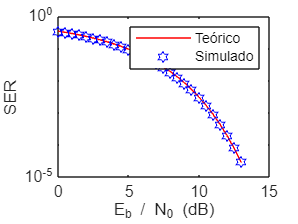

figure(1);
semilogy(EbNodB, SER_teo, 'r-');
hold on
semilogy(EbNodB, serSim8PSK, 'bh');
legend('Teórico', 'Simulado');
hold off
xlabel('E_b / N_0 (dB)');
ylabel('SER');

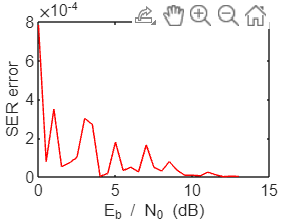

figure(2);
plot(EbNodB, SER_error, 'r-');
hold on;
xlabel('E_b / N_0 (dB)');
ylabel('SER error');

hold off;

Item c)

EbNodB = 0 :  0.5 : 13;
EbNoPow = db2pow(EbNodB);
L = length(EbNodB);
L_msg = 1e4;
iterations = 500;
SER_teo = zeros(1,L);
SER_teo_DPSK = zeros(1,L);
func = @(x, c) exp(-log2(8).*c.*(1-cos(pi/8).*cos(x)))./(1-cos(pi/8).*cos(x));
diversityGain = zeros(1,L);

serSim8PSK_0 = zeros(1,L);
serSim8PSK_1 = zeros(1,L);
serSim8PSK_2 = zeros(1,L);
serSim8PSK_3 = zeros(1,L);
serSim8PSK_4 = zeros(1,L);
serSim8PSK_5 = zeros(1,L);

theta0 = pi/16;
theta1 = pi/8;
theta2 = pi/4;
theta3 = pi/2;
theta4 = pi;
theta5 = pi/32;
for j = 1:L
    EbNo = EbNoPow(j);
    SER_teo(j) = pTeo_8PSK(EbNo);
    SER_teo_DPSK(j) = pTeo_8DPSK(EbNo, func);
    diversityGain(j) = pow2db(SER_teo_DPSK(j)/SER_teo(j));
    err8PSK_0 = 0;
    err8PSK_1 = 0;
    err8PSK_2 = 0;
    err8PSK_3 = 0;
    err8PSK_4 = 0;
    err8PSK_5 = 0;
    for i = 1 : iterations
        % 8-DPSK:
        M = 8;
        msg = randi([0,M-1],[1, L_msg]);
        tamanho = size(msg);
        s_0 = dpskmod(msg,M,theta0);
        s_1 = dpskmod(msg,M,theta1);
        s_2 = dpskmod(msg,M,theta2);
        s_3 = dpskmod(msg,M,theta3);
        s_4 = dpskmod(msg,M,theta4);
        s_5 = dpskmod(msg,M,theta5);
        AWGN = sqrt(1/(2*EbNoPow(j)*log2(M)))*randn(tamanho) +...
               1j*sqrt(1/(2*EbNoPow(j)*log2(M)))*randn(tamanho);
        y_0 = s_0 + AWGN;
        y_1 = s_1 + AWGN;
        y_2 = s_2 + AWGN;
        y_3 = s_3 + AWGN;
        y_4 = s_4 + AWGN;
        y_5 = s_5 + AWGN;
        s_hat_0 = dpskdemod(y_0,M,theta0);
        s_hat_1 = dpskdemod(y_1,M,theta1);
        s_hat_2 = dpskdemod(y_2,M,theta2);
        s_hat_3 = dpskdemod(y_3,M,theta3);
        s_hat_4 = dpskdemod(y_4,M,theta4);
        s_hat_5 = dpskdemod(y_5,M,theta5);
        err8PSK_0 = err8PSK_0 + nnz(s_hat_0 - msg);
        err8PSK_1 = err8PSK_1 + nnz(s_hat_1 - msg);
        err8PSK_2 = err8PSK_2 + nnz(s_hat_2 - msg);
        err8PSK_3 = err8PSK_3 + nnz(s_hat_3 - msg);
        err8PSK_4 = err8PSK_4 + nnz(s_hat_4 - msg);
        err8PSK_5 = err8PSK_5 + nnz(s_hat_5 - msg);

        serSim8PSK_0(j) = err8PSK_0 / (L_msg*iterations);
        serSim8PSK_1(j) = err8PSK_1 / (L_msg*iterations);
        serSim8PSK_2(j) = err8PSK_2 / (L_msg*iterations);
        serSim8PSK_3(j) = err8PSK_3 / (L_msg*iterations);
        serSim8PSK_4(j) = err8PSK_4 / (L_msg*iterations);
        serSim8PSK_5(j) = err8PSK_5 / (L_msg*iterations);
    end
end
meanDiversityGain = mean(diversityGain)

meanDiversityGain = 7.0415

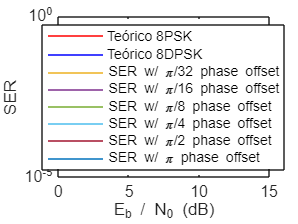

figure(3);
semilogy(EbNodB, SER_teo, 'r-');
hold on
semilogy(EbNodB, SER_teo_DPSK, 'b-');
semilogy(EbNodB, serSim8PSK_5);
semilogy(EbNodB, serSim8PSK_0);
semilogy(EbNodB, serSim8PSK_1);
semilogy(EbNodB, serSim8PSK_2);
semilogy(EbNodB, serSim8PSK_3);
semilogy(EbNodB, serSim8PSK_4);
legend('Teórico 8PSK', 'Teórico 8DPSK', 'SER w/ \pi/32 phase offset', 'SER w/ \pi/16 phase offset', ...
    'SER w/ \pi/8 phase offset', 'SER w/ \pi/4 phase offset', ...
    'SER w/ \pi/2 phase offset', 'SER w/ \pi phase offset','Location', 'best');
hold off
xlabel('E_b / N_0 (dB)');
ylabel('SER');

function p = pTeo_8PSK(EbNo)
    M = 8;
    p = 2*qfunc(sqrt(2*log2(M)*EbNo)*sin(pi/M));
end

function I = simpson_13integrate(func, x0, xf, segNumber)
    X = linspace(x0,xf,segNumber+1);
    Y = func(X);
    evenSum = 0; oddSum = 0;
    for i = 2 : 2 : segNumber
        evenSum = evenSum + Y(i);
    end
    for i = 3 : 2 : segNumber-1
        oddSum = oddSum + Y(i);
    end
    I = (xf-x0)*(Y(1)+2*evenSum + 4*oddSum + Y(segNumber+1))/(3*segNumber);
end

function p = pTeo_8DPSK(EbNo, func)
    M = 8;
    p = (sin(pi/M)/(2*pi))*simpson_13integrate(@(x) func(x,EbNo), -pi/2, pi/2, 30);
end